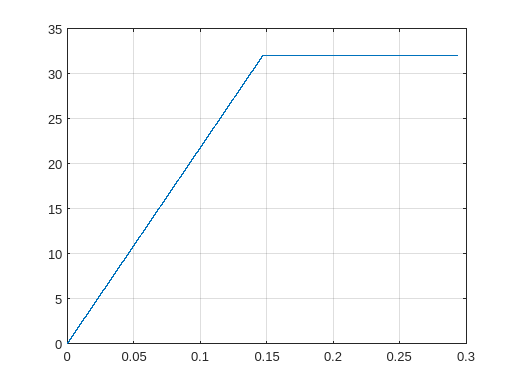

clc; clear all; close all;

% This is Hydraulic System number 3 . rho (density) = 875 kg/m^3 . beta (bulk modulus) = 1100 MPa . Minimum gauge pressure (vacuum) = -1 bar , Qs01 = 32 l/min , V1 = 588 cm^3 , V2 = 564 cm^3 , V3 = 285 cm^3 , V4 = 945 cm^3 , Cd1 = 0.89 , Ad1 = 28 mm^2 , Cd2 = 0.62 , Ad2 = 35 mm^2 , Cd3 = 0.59 , Ad3 = 39 mm^2 , Cd4 = 0.53 , Ad4 = 36 mm^2 , Cd5 = 0.49 , Ad5 = 29 mm^2 , Cd6 = 0.81 , Ad6 = 27 mm^2 , tRU1 = 147 milliSeconds , p1 (initial value) = 0 bar , p2 (initial value) = 0 bar , p3 (initial value) = 0 bar , p4 (initial value) = 0 bar , simulation time = 294 milliSeconds . What is the maximum absolute value of the p3 pressure [bar] ?

rho = 875; % kg/m^3
beta = 1100*10^6; % Pa
gauge_min = -10^5; % Pa

Qs01 = 32 / (60*10^3); % m^3
V1 = 588/10^6; % m^3
V2 = 564/10^6; % m^3
V3 = 285/10^6; % m^3
V4 = 945/10^6; % m^3

Cd1 = 0.89;
Ad1 = 28/10^6; % m^2
Cd2 = 0.62;
Ad2 = 35/10^6; % m^2
Cd3 = 0.59;
Ad3 = 39/10^6; % m^2
Cd4 = 0.53;
Ad4 = 36/10^6; % m^2
Cd5 = 0.49;
Ad5 = 29/10^6; % m^2
Cd6 = 0.81;
Ad6 = 27/10^6; % m^2

tRU1 = 147/1000; % s

p1 = 0;
p2 = 0;
p3 = 0;
p4 = 0;

simTime = 294/1000; % s
t = 0; % s
dt = 10^-5; % s
idx = 1;

while(t <= simTime)
    % Calculations
    if(t<tRU1)
        Qs1 = Qs01 * t/tRU1;
    else
        Qs1 = Qs01;
    end
    
    Q1 = Cd1*Ad1*sign(p1-p3)*sqrt(2/rho*abs(p1-p3));
    Q2 = Cd2*Ad2*sign(p2-p1)*sqrt(2/rho*abs(p2-p1));
    Q3 = Cd3*Ad3*sign(p2-p3)*sqrt(2/rho*abs(p2-p3));
    Q4 = Cd4*Ad4*sign(p2)*sqrt(2/rho*abs(p2));
    Q5 = Cd5*Ad5*sign(p3-p4)*sqrt(2/rho*abs(p3-p4));
    Q6 = Cd6*Ad6*sign(p4)*sqrt(2/rho*abs(p4));

    p1Dot = beta/V1 * (Q2-Q1);
    p2Dot = beta/V2 * (Qs1-Q2-Q3-Q4);
    p3Dot = beta/V3 * (Q1+Q3-Q5);
    p4Dot = beta/V4 * (Q5-Q6);

    % Logging
    tplt(idx) = t;
    Qs1plt(idx) = Qs1;
    p3plt(idx) = p3;

    % Time integrate
    p1 = p1 + p1Dot * dt;
    if p1 < gauge_min
        p1 = gauge_min;
    end
    p2 = p2 + p2Dot * dt;
    if p2 < gauge_min
        p2 = gauge_min;
    end
    p3 = p3 + p3Dot * dt;
    if p3 < gauge_min
        p3 = gauge_min;
    end
    p4 = p4 + p4Dot * dt;
    if p4 < gauge_min
        p4 = gauge_min;
    end

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(tplt,Qs1plt*60*10^3)
grid

hold off

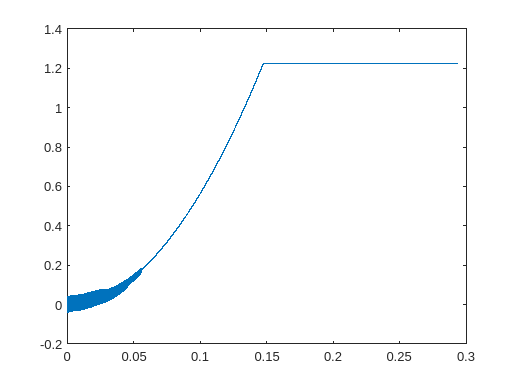

plot(tplt, p3plt/10^5)


p3min = min(p3plt)/10^5

p3min =        -0.0393707302413737


p3max = max(p3plt)/10^5

p3max =           1.22673801610075
